Longitud total de la columna de cargas negativas: 5 m
Longitud total de la columna de cargas positivas: 5 m
Fuerza total debida a las cargas negativas en (0,0,0): 1.8796 N
Fuerza total debida a las cargas positivas en (0,0,0): 0.4505 N
Fuerza total en (0,0,0) (suma de ambas): 1.4406 N


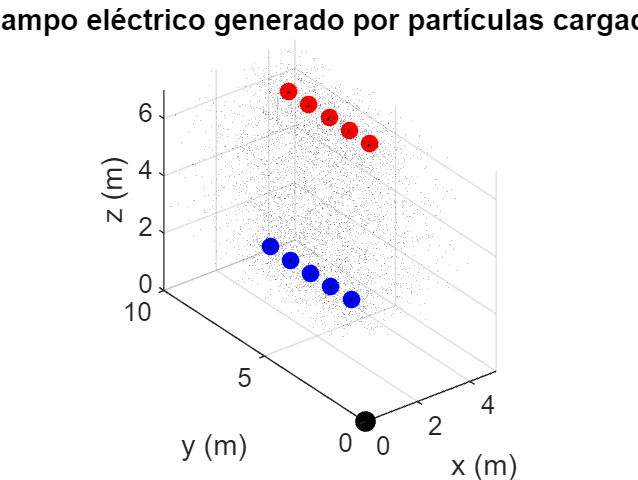

% Define los parámetros de entrada
nNegativas = 5;
nPositivas = 5;
direccion = 'h';
x1_neg = 1;
y1_neg = 2;
z1_neg = 3;
x1_pos = 4;
y1_pos = 5;
z1_pos = 6;

% Llama a la función
electric_field_simulation(nNegativas, nPositivas, direccion, x1_neg, y1_neg, z1_neg, x1_pos, y1_pos, z1_pos);

function electric_field_simulation(nNegativas, nPositivas, direccion, x1_neg, y1_neg, z1_neg, x1_pos, y1_pos, z1_pos)
   
    % Definición de constantes
    k = 8.987551787e9; % Constante de Coulomb en Nm²/C²
    q1 = -1e-9; % Magnitud de la carga negativa en C
    q2 = 1e-9; % Magnitud de la carga positiva en C

    % Calcula la longitud total de las filas de cargas (asumiendo que cada carga está separada por 1 metro)
    longitudFilaNegativas = nNegativas;
    longitudFilaPositivas = nPositivas;

    % Muestra la longitud de las filas de cargas
    fprintf('Longitud total de la columna de cargas negativas: %d m\n', longitudFilaNegativas);
    fprintf('Longitud total de la columna de cargas positivas: %d m\n', longitudFilaPositivas);

    % Determina las posiciones de las siguientes cargas basadas en la dirección y las primeras cargas
    positions_negativas = [];
    positions_positivas = [];
    if strcmp(direccion, 'h')
        positions_negativas = [x1_neg*ones(nNegativas, 1) y1_neg + (0:nNegativas-1).' z1_neg*ones(nNegativas, 1)];
        positions_positivas = [x1_pos*ones(nPositivas, 1) y1_pos + (0:nPositivas-1).' z1_pos*ones(nPositivas, 1)];
    elseif strcmp(direccion, 'v')
        positions_negativas = [x1_neg*ones(nNegativas, 1) y1_neg*ones(nNegativas, 1) z1_neg + (0:nNegativas-1).'];
        positions_positivas = [x1_pos*ones(nPositivas, 1) y1_pos*ones(nPositivas, 1) z1_pos + (0:nPositivas-1).'];
    else
        error('Dirección no reconocida. Ingrese "horizontal" o "vertical".');
    end

    % Combinar todas las posiciones y cargas
    positions = [positions_negativas; positions_positivas];
    charges = [repmat(q1, nNegativas, 1); repmat(q2, nPositivas, 1)];

    % Definir el rango de coordenadas para la visualización
    x_range = linspace(min(positions(:,1))-1, max(positions(:,1))+1, 100);
    y_range = linspace(min(positions(:,2))-1, max(positions(:,2))+1, 100);
    z_range = linspace(min(positions(:,3))-1, max(positions(:,3))+1, 100);

    % Generar una malla de puntos en el espacio
    [X, Y, Z] = meshgrid(x_range, y_range, z_range);

    % Inicializar campos eléctricos en cero
    Ex = zeros(size(X));
    Ey = zeros(size(Y));
    Ez = zeros(size(Z));

    % Calcular el campo eléctrico debido a cada partícula
    for idx = 1:length(charges)
        px = positions(idx, 1);
        py = positions(idx, 2);
        pz = positions(idx, 3);
        charge = charges(idx);

        r = sqrt((X - px).^2 + (Y - py).^2 + (Z - pz).^2); % Matriz de distancias al punto (x, y, z)
        Ex = Ex + k * charge * (X - px) ./ r.^3;
        Ey = Ey + k * charge * (Y - py) ./ r.^3;
        Ez = Ez + k * charge * (Z - pz) ./ r.^3;
    end

    % Calcular las fuerzas en el punto (0,0,0)
    force_negativas = [0 0 0];
    force_positivas = [0 0 0];
    force_total = [0 0 0];

    for idx = 1:length(charges)
        px = positions(idx, 1);
        py = positions(idx, 2);
        pz = positions(idx, 3);
        charge = charges(idx);
        r = sqrt(px^2 + py^2 + pz^2); % Distancia al punto (0, 0, 0)
        if r ~= 0 % Evita la división por cero
            force = k * charge / r^2 * [px py pz] / r;
            if charge < 0 % Si es carga negativa
                force_negativas = force_negativas + force;
            else % Si es carga positiva
                force_positivas = force_positivas + force;
            end
            force_total = force_total + force;
        end
    end

    % Mostrar las fuerzas
    fprintf('Fuerza total debida a las cargas negativas en (0,0,0): %.4f N\n', norm(force_negativas));
    fprintf('Fuerza total debida a las cargas positivas en (0,0,0): %.4f N\n', norm(force_positivas));
    fprintf('Fuerza total en (0,0,0) (suma de ambas): %.4f N\n', norm(force_total));

    % Visualizar el campo eléctrico con quiver3
    figure; % Asegura que se cree una nueva figura para la visualización
    quiver3(X, Y, Z, Ex, Ey, Ez, 'k');
    hold on; % Mantener el gráfico actual para añadir las bolitas
    % Añadir bolitas rojas para cargas positivas y azules para negativas
    scatter3(positions_negativas(:,1), positions_negativas(:,2), positions_negativas(:,3), 'bo', 'filled');
    scatter3(positions_positivas(:,1), positions_positivas(:,2), positions_positivas(:,3), 'ro', 'filled');
    scatter3(0, 0, 0, 50, 'k', 'filled');

    xlabel('x (m)');
    ylabel('y (m)');
    zlabel('z (m)');
    title('Campo eléctrico generado por partículas cargadas');
    axis equal;
    hold off; % Finalizar la adición de gráficos
end
